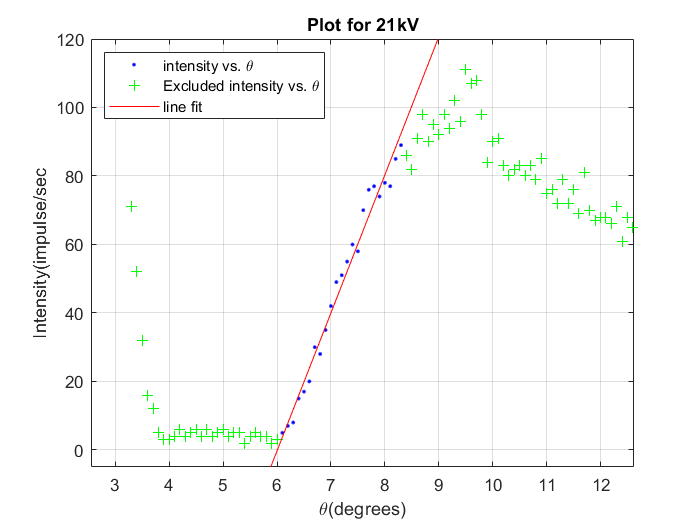

[xData, yData] = prepareCurveData( theta21kV, R21kV );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 90 91 92 93 94 95 96 97 98 99 100 101 102 103 104 105 106 107 108 109 110 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128 129 130 131 132 133 134 135 136 137 138 139 140 141 142 143 144 145 146 147 148 149 150 151 152 153 154 155 156 157 158 159 160 161 162 163 164 165 166 167 168 169 170 171] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'R21kV vs. theta21kV', 'Excluded R21kV vs. theta21kV', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel theta21kV
ylabel R21kV
grid on

xlim([2.55 12.62])
ylim([-5 120])
legend({'intensity vs. \theta','Excluded intensity vs. \theta','line fit'},'Location','northwest')
title('Plot for 21kV')
xlabel('\theta(degrees)')
ylabel('Intensity(impulse/sec')


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =       40.31  (37.71, 42.9)     \pm1.30
 %      p2 =      -242.1  (-260.9, -223.4)  \pm9.4

%Goodness of fit:
 % SSE: 330.9
  %R-square: 0.9803
 % Adjusted R-square: 0.9793
  %RMSE: 3.969
  
  %\theta_m=6.006 \pm 0.303